# Laboratorio 2 

## Robótica 2021 - 1 

### Luis Alberto Chavez Castro

### Jorge Luis Reina Jara

### Edwin Alexander Casallas Moreno

##  Modelo cinemático inverso *fanuc LR Mate 200 ib*

### **Parte I, Robot y Ruta.**

El robot asignado para el desarrolllo de este laboratorio fue el modelo* fanuc LR Mate 200 ib, Se asigna un modelo de robot industrial a cada equipo de trabajo y un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentar al menos la simulación de esa ruta, pueden crear y simular otras rutas y/o otros planos..*

### Localización de ruta.

Plano - Vector, significa que la ruta que el robot va a simular debe estar en un plano normal al vector indicado en la tabla.

La ruta debe tener una de las dos formas mostradas en la figura 2. Cada grupo selecciona la que deseen.

La dimensión L debe ser aproximadamente 0,4 del alcance horizontal máximo del robot.

El grupo decide la posición de la ruta en el espacio cartesiano de manera que quede dentro del espacio diestro del robot.

la ruta seleccionada por el equipo de trabajo es la que se muestra a continuación:

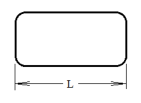

### Características y modelo del robot

Busque información t´ ecnica del robot, obtenga catálogos de fabricante, presente en el informe:

#### 1. Imagen del robot.

el Robot a modelar es el modelo LR Mate 200iB de Fanuc, que se muestra en el modelo siguiente y se muestra en una fotografia en la siguiente imagen:

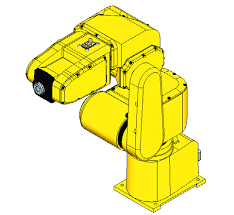

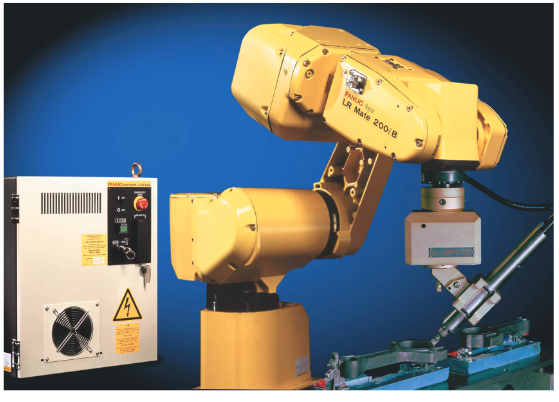

#### 2. Capacidad de carga.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB posee una capacidad de carga de 7Kg basados en el Datasheet aunque la mayoria de distribuidores solo hacian promocion de una capacidad de carga de maximo 5kg.

#### 3. Alcance vertical y horizontal.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB hace parte de la gama de mini robots que buscan emular las longitudes de un brazo humano.

En su punto máximo suerior logra 970mm en altura, medidos desde la base de instalacion del robot, hacia el frente logra su extension de 770mm desde su origen.

#### 4. Repetibilidad.

La repetiiblidad de este robot esta el rango de las centecimas de milimetro, segun el fabricante es de +/-0.04 mm.

#### 5. Gráfica(s) de espacio alcanzable.

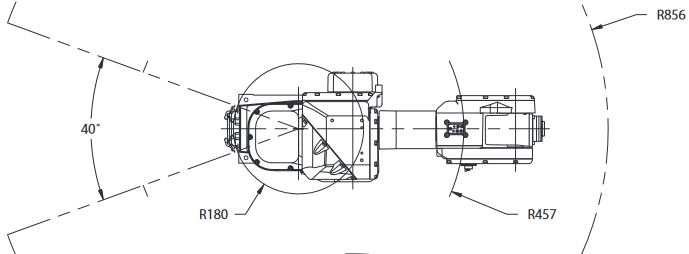

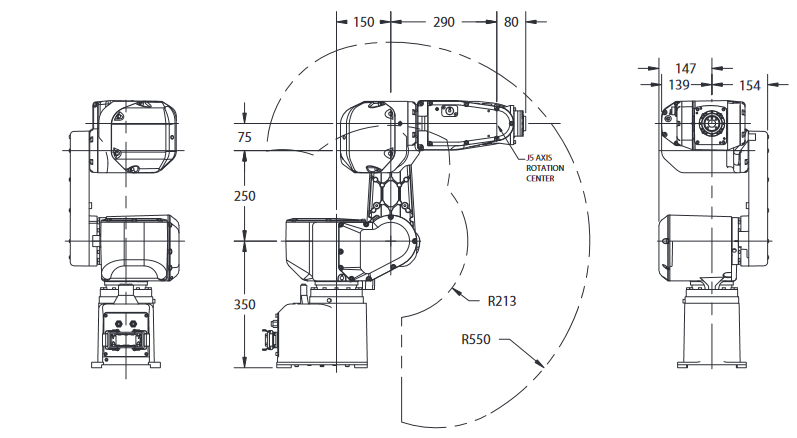

#### 6. Tabla de parámetros DH.

# 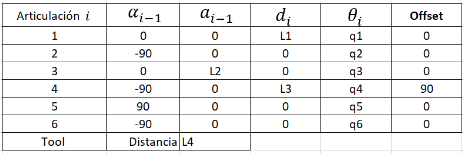

#### 7. Qué software utiliza el fabricante para diseño de celdas o programación.

el Fabricante Fanuc, emplea su propio software llamado  ROBOTSE SOFTWARE y para este robot el controlador  estándar de Fanuc  R-30iB Plus  es el que mejor se adapta a las necesidades de control de este modelo en especifico.

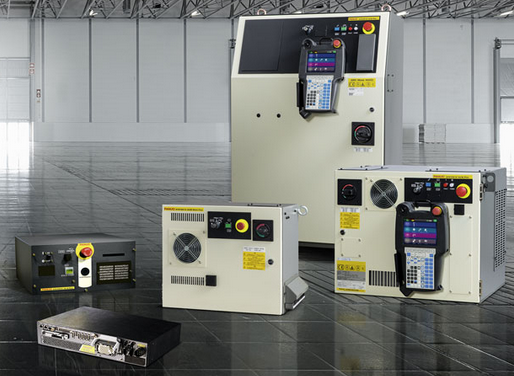

por otra parte se el mando a distancia en esta familia de robots se conoce como i-pendant y se muestra a continuacion:

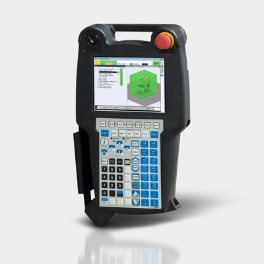

### Modelos

#### Peter Corke


%% Robot RPRRR 5 gdl
clf
clc


W = [-100 100 -100 100 -60 110]*10; %Volumen a graficar

 plot_options = {'workspace',W,'scale', 0.8,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[700 700 1000] };


L1=350;
L2=150;
L3=250;
L4=75;
L5=450;
L6=80;

%            Theta  d   a   alpha  type mdh offset  qlim

L(1) = Link('revolute'   ,'alpha',     0,  'a',  0,  'd', L1 , 'offset',     0, 'qlim',  [-160*pi/180 160*pi/180], 'modified');
L(2) = Link('revolute'   ,'alpha', -pi/2,  'a',  L2, 'd',  0 , 'offset',  -pi/2, 'qlim', [-35*pi/180  150*pi/180], 'modified');
L(3) = Link('revolute'   ,'alpha',     0,  'a',  L3, 'd',   0, 'offset',     0, 'qlim',  [-110*pi/180 206*pi/180], 'modified');
L(4) = Link('revolute'   ,'alpha', -pi/2,  'a',  L4, 'd',  L5, 'offset',     0, 'qlim',  [-190*pi/180 190*pi/180], 'modified');
L(5) = Link('revolute'   ,'alpha',  pi/2,  'a',  0,  'd',   0, 'offset',     0, 'qlim',  [-120*pi/180 120*pi/180], 'modified');
L(6) = Link('revolute'   ,'alpha', -pi/2,  'a',  0,  'd',   0, 'offset',     0, 'qlim',  [-360*pi/180 360*pi/180], 'modified');

Robot_Fanuc = SerialLink(L,'name','Fanuc LR mate 200iB','plotopt',plot_options)

 
Robot_Fanuc = 
 
Fanuc LR mate 200iB (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        350|          0|          0|          0|
|  2|         q2|          0|        150|     -1.571|     -1.571|
|  3|         q3|          0|        250|          0|          0|
|  4|         q4|        450|         75|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|          0|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0      

H=[10 10 10];
%Robot_Fanuc.plot((0 pi/2 -pi/2 0 0 0))
%%
Robot_Fanuc.tool = [ 0  0   1  H(1);... %ubicacion herramienta
                     1  0   0  H(2) ;...
                     0  1   0  H(3) ;...
                     0  0   0  1  ];
    
%%

%q = [0 pi/2 -pi/2 0 0 0]; %posicion Home
q = [0 0 0 0 pi/2 0]; %posicion Home

Robot_Fanuc.teach(q) %se almacena una posicion especifica como HOME
hold on
trplot(eye(4),'length',2 )

%% cinematica inversa por el metodo de geometrico directo
TCP = Robot_Fanuc.fkine(q)  % ikine

TCP =     0.0000    1.0000    0.0000  610.0000
   -1.0000    0.0000   -0.0000  -10.0000
   -0.0000   -0.0000    1.0000  685.0000
         0         0         0    1.0000


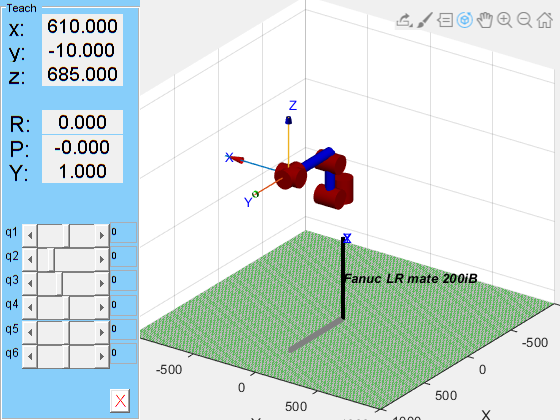

trplot(TCP,'length',2 )

tr2rpy(TCP,'zyx','deg')

ans =   -90.0000    0.0000   -0.0000



%% para las trayectorias se emplea:
T0=transl( 1.0, 3, 1) * trotx(pi/2);
T1=transl(1.8, 3, 1) * trotx(pi/2);
T = ctraj(T0, T1, 50);
T(:,:,1)  %primera pose

ans =     1.0000         0         0    1.0000
         0    0.0000   -1.0000    3.0000
         0    1.0000    0.0000    1.0000
         0         0         0    1.0000


T(:,:,10) %decima pose

ans =     1.0000         0         0    1.0607
         0    0.0000   -1.0000    3.0000
         0    1.0000    0.0000    1.0000
         0         0         0    1.0000


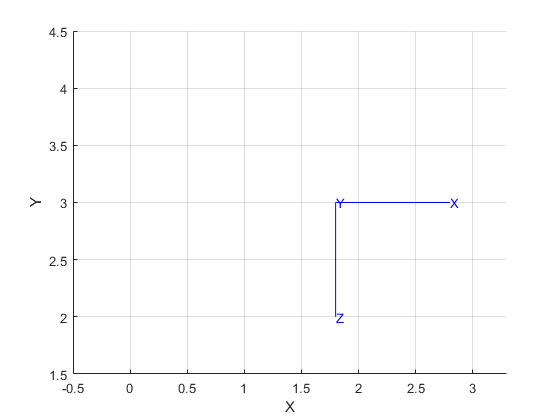

clf; tranimate(T)

%Matriz del primer link
Robot_FanucT1=L6(1).A(q1);

Unrecognized function or variable 'q1'.

for i=1:4
    for j=1:4
        [C,T]=coeffs(Robot_FanucT1(i,j));
        C=round(C);
        Robot_FanucT1(i,j)=dot(C,T);
    end
end
Robot_FanucT1
%Matriz del segundo link 
Robot_FanucT2=L6(2).A(q1);
for i=1:4
    for j=1:4
        [C,T]=coeffs(Robot_FanucT2(i,j));
        C=round(C);
        Robot_FanucT2(i,j)=dot(C,T);
    end
end
Robot_FanucT2
%Matriz del tercer link 
Robot_FanucT3=L6(3).A(q3);
for i=1:4
    for j=1:4
        [C,T]=coeffs(Robot_FanucT3(i,j));
        C=round(C);
        Robot_FanucT3(i,j)=dot(C,T);
    end
end
Robot_FanucT3
%Matriz del cuarto link 
Robot_FanucT4=L6(4).A(q4);
for i=1:4
    for j=1:4
        [C,T]=coeffs(Robot_FanucT4(i,j));
        C=round(C);
        Robot_FanucT4(i,j)=dot(C,T);
    end
end
Robot_FanucT4
%Matriz del quinto link 
Robot_FanucT5=L6(5).A(q5);
for i=1:4
    for j=1:4
        [C,T]=coeffs(Robot_FanucT5(i,j));
        C=round(C);
        Robot_FanucT5(i,j)=dot(C,T);
    end
end
Robot_FanucT5
%Matriz del sexto link 
Robot_FanucT6=L6(6).A(q6);
for i=1:4
    for j=1:4
        [C,T]=coeffs(Robot_FanucT6(i,j));
        C=round(C);
        Robot_FanucT6(i,j)=dot(C,T);
    end
end
Robot_FanucT6

PARTE 3

JACOBIANO